# Phase3 : Pratical Phase :

% in this Phase we are going to implement Kalman Filter :
% We have its transfer function which is calculated through System
% Identification
% import Data From .mat
tf2

tf2 =
 
  From input "u1" to output "y1":
          16.33
  ---------------------
  s^2 + 4.334 s + 17.95
 
Name: tf2
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 86.93% (stability enforced)
FPE: 4661, MSE: 4233                               


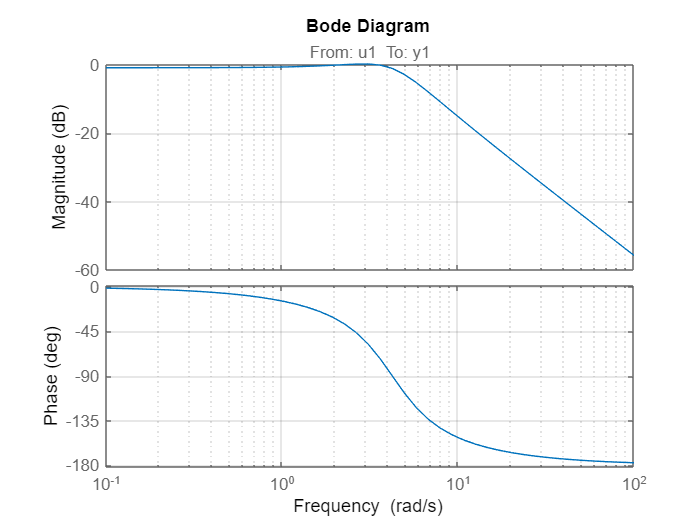

bode(tf2)
grid on

% This is in a unity feedback loop but we need open loop transfer function
%so :
g

g =
 
         16.33
  --------------------
  s^2 + 4.334 s + 1.62
 
Continuous-time transfer function.



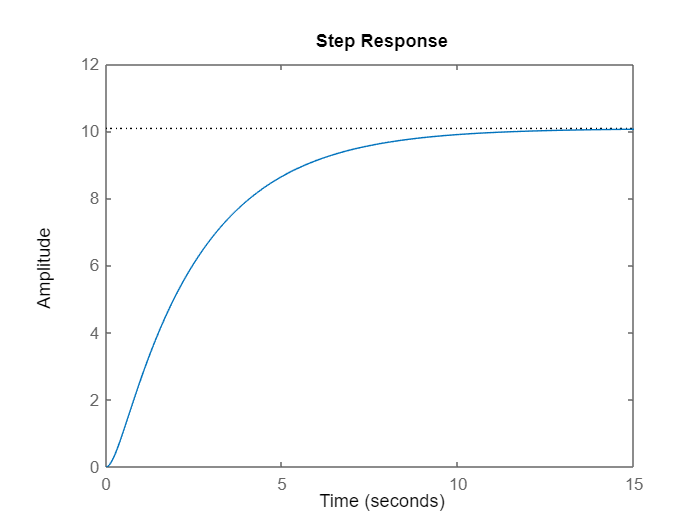

step(g)

## Minimal Realization

numg = 16.33;
denumg = [1 4.334 1.62];
[A , B , C , D] = tf2ss(numg , denumg);
A1 = vpa(sym(A))

$$A1 = \left(\begin{array}{cc} -4.334 & -1.62\\ 1.0 & 0 \end{array}\right)$$

B2 = vpa(sym(B))

$$B2 = \left(\begin{array}{c} 1.0\\ 0 \end{array}\right)$$

C3 = vpa(sym(C))

$$C3 = \left(\begin{array}{cc} 0 & 16.33 \end{array}\right)$$